% Cargar los datos 
database = readtable('nac2015.csv');
data = readtable('nac2015.csv'); % 
data_cauca = data(data.COD_DPTO == 20, :);
data = data_cauca; % Ajusta el nombre del archivo

% Asegurarnos que FECHA_NACM sea del tipo fecha
data.FECHA_NACM = datetime(data.FECHA_NACM, 'InputFormat', 'dd/MM/yyyy');


% Selec
% cionar las columnas de interés, excluyendo FECHA_NACM
X = data(:, {'AREANAC', 'PESO_NAC', 'TALLA_NAC', 'T_GES', 'NUMCONSUL', ...
    'TIPO_PARTO',  'EDAD_MADRE','EST_CIVM', 'IDPERTET', ...
    'NIV_EDUM'});
I1 = find(data.N_HIJOSV >= 1);
% Paso 1: Eliminar filas con valores faltantes (NaN)

X =  rmmissing(X);
y = data.N_HIJOSV >= 2; % 1 si tiene más de un hijo, 0 si no.
%y = y(idxUnique); % Ajustar la variable objetivo correspondiente
X = normalize(X);
% Paso 3: Normalización de datos



maxIter = 120;          % Número máximo de iteraciones
f1_threshold = 0.8;    % Umbral deseado de F1-score
bestF1Score = 0;        % Mejor F1-score encontrado
numIter = 0;            % Contador de iteraciones
bestModel = [];         % Variable para almacenar el mejor modelo
bestConfMat = [];       % Matriz de confusión del mejor modelo

% Paso 4: División de datos en conjunto de entrenamiento y prueba
while bestF1Score <= f1_threshold && numIter < maxIter
    numIter = numIter + 1;
    cv = cvpartition(y, 'Holdout', 0.3); % 30% para prueba
    X_train = X(training(cv), :);
    X_test = X(test(cv), :);
    y_train = y(training(cv));
    y_test = y(test(cv));
    X_norm = normalize(X, 'scale');
    X_numeric = table2array(X_norm);
    % Paso 5: Ajuste del modelo KNN con búsqueda de hiperparámetros
    mdl = fitcknn(X_train, y_train, ...
        'NumNeighbors', 31, ... % Número inicial de vecinos
        'Distance', 'cityblock', ... % Distancia euclidiana
        'DistanceWeight',  'equal',... 
        'Standardize', false);
    
    
      y_pred = predict(mdl, X_test);
    
        % Calcular métricas
        [confMat, ~] = confusionmat(y_test, y_pred);
        TP = confMat(2,2); % Verdaderos Positivos
        FN = confMat(2,1); % Falsos Negativos
        FP = confMat(1,2); % Falsos Positivos
        TN = confMat(1,1); % Verdaderos Negativos
    
        precision = TP / (TP + FP);
        recall = TP / (TP + FN);
        f1_score = 2 * (precision * recall) / (precision + recall);
    
          % --- Almacenar el mejor modelo basado en F1-score ---
        if f1_score > bestF1Score
            bestF1Score = f1_score;
            bestRecall = recall;
            bestPresicion = precision;
            bestConfMat = confMat;
            bestModel = mdl;
        end
               % Mostrar métricas de iteración
        fprintf('numIter %.2f F1-Score: %.2f%% | Recall: %.2f%% | Precision: %.2f%%\n', ...
             numIter , f1_score * 100, recall * 100, precision * 100);
        fprintf('_______ Best F1-Score: %.2f%% | BEST Recall: %.2f%% |  BEST Precision: %.2f%%\n ______', ...
               bestF1Score* 100, bestRecall* 100, bestPresicion* 100);

end

numIter 1.00 F1-Score: 79.97% | Recall: 83.91% | Precision: 76.39%


_______ Best F1-Score: 79.97% | BEST Recall: 83.91% |  BEST Precision: 76.39%
 ______

numIter 2.00 F1-Score: 79.65% | Recall: 83.65% | Precision: 76.01%


_______ Best F1-Score: 79.97% | BEST Recall: 83.91% |  BEST Precision: 76.39%
 ______

numIter 3.00 F1-Score: 79.58% | Recall: 83.85% | Precision: 75.73%


_______ Best F1-Score: 79.97% | BEST Recall: 83.91% |  BEST Precision: 76.39%
 ______

numIter 4.00 F1-Score: 79.43% | Recall: 83.60% | Precision: 75.65%


_______ Best F1-Score: 79.97% | BEST Recall: 83.91% |  BEST Precision: 76.39%
 ______

numIter 5.00 F1-Score: 79.59% | Recall: 83.04% | Precision: 76.42%


_______ Best F1-Score: 79.97% | BEST Recall: 83.91% |  BEST Precision: 76.39%
 ______

numIter 6.00 F1-Score: 79.45% | Recall: 82.76% | Precision: 76.40%


_______ Best F1-Score: 79.97% | BEST Recall: 83.91% |  BEST Precision: 76.39%
 ______

numIter 7.00 F1-Score: 79.79% | Recall: 83.60% | Precision: 76.31%


_______ Best F1-Score: 79.97% | BEST Recall: 83.91% |  BEST Precision: 76.39%
 ______

numIter 8.00 F1-Score: 79.07% | Recall: 83.10% | Precision: 75.42%


_______ Best F1-Score: 79.97% | BEST Recall: 83.91% |  BEST Precision: 76.39%
 ______

numIter 9.00 F1-Score: 79.47% | Recall: 82.29% | Precision: 76.83%


_______ Best F1-Score: 79.97% | BEST Recall: 83.91% |  BEST Precision: 76.39%
 ______

numIter 10.00 F1-Score: 79.19% | Recall: 82.43% | Precision: 76.21%


_______ Best F1-Score: 79.97% | BEST Recall: 83.91% |  BEST Precision: 76.39%
 ______

numIter 11.00 F1-Score: 80.03% | Recall: 83.40% | Precision: 76.91%


_______ Best F1-Score: 80.03% | BEST Recall: 83.40% |  BEST Precision: 76.91%
 ______

fprintf('--------------------MODELO FINAL -----------------------------------')

--------------------MODELO FINAL -----------------------------------

fprintf('_______ Best F1-Score: %.2f%% | BEST Recall: %.2f%% |  BEST Precision: %.2f%%\n ______', ...
               bestF1Score* 100, bestRecall* 100, bestPresicion* 100);

_______ Best F1-Score: 80.03% | BEST Recall: 83.40% |  BEST Precision: 76.91%
 ______


% Nueva matriz de confusión y métricas
[bestConfMat, ~] = confusionmat(y_test, y_pred)

bestConfMat =         1786         896
         594        2985


recall_opt = bestConfMat(2,2) / sum(bestConfMat(2,:));
fprintf('Recall optimizado: %.2f%%\n', recall_opt * 100);

Recall optimizado: 83.40%


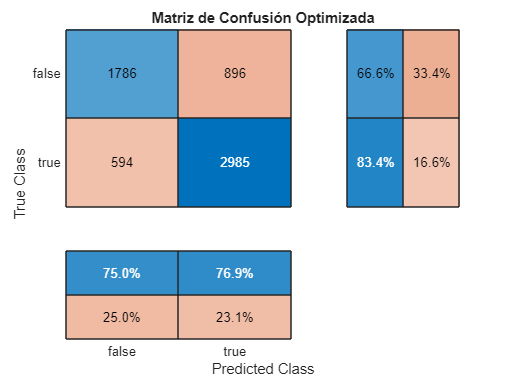

% Graficar la matriz de confusión
confusionchart(confMat, {'false', 'true'}, ...
    'Title', 'Matriz de Confusión Optimizada', ...
    'RowSummary', 'row-normalized', ...
    'ColumnSummary', 'column-normalized');